b=1;
z=roots(b)


z =

  0×1 empty double column vector



a=[1 -0.9];
p=roots(a)

p = 0.9000

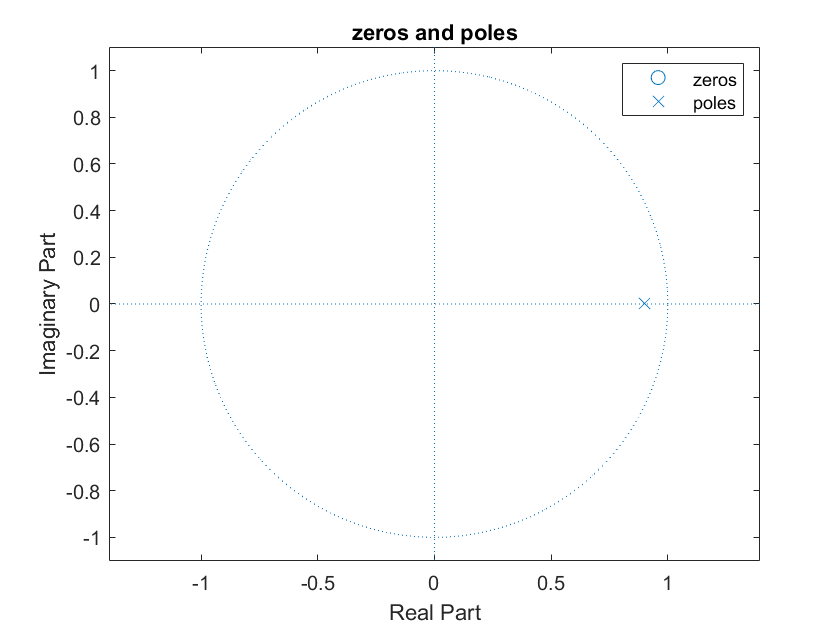


zplane(z,p)
title('zeros and poles')
legend('zeros','poles')


poly(z)

ans = 1

poly(p)

ans =     1.0000   -0.9000


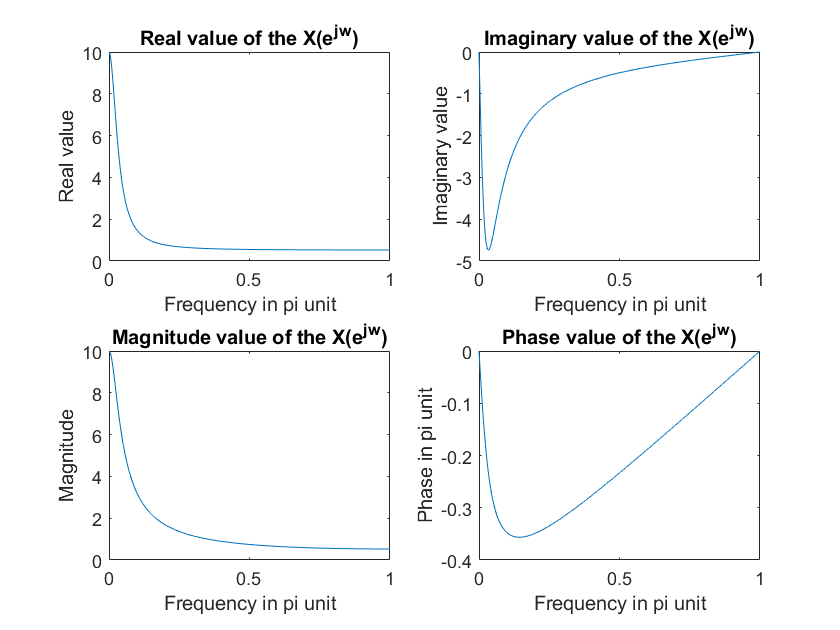

% [H,w]=freqz(b,a,n)
K=500;
k=0:K;
w=pi*k/K;
[H,w]=freqz(b,a,w);

dfp4(H,w)

[i,n]=impulseseq(0,7,0)

i = 1×8 logical array
   1   0   0   0   0   0   0   0


n =      0     1     2     3     4     5     6     7


h=filter(b,a,i)

h =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783


hv=0.9.^n

hv =     1.0000    0.9000    0.8100    0.7290    0.6561    0.5905    0.5314    0.4783


error=max(abs(h-hv))

error = 1.1102e-16